# Striketime Code

Run this from the directory containing the data files

Point of this code is to find events and their amplitudes. Input parameters for this include a minimum threshold amplitude. Currently there is the thought of handling spikes in a detected non-zero background. To run the same spike finding algoryhtm one needs to perform a "basethresh" filter where all data below basethresh (a.k.a. cut threeshold in bd_175) are set to zero. This facilitates bracketing events with zeros as would be the case for the "clean" single particle events BAS assumes. This type of application HAS NOT BEEN TESTED. At the very least, need to confirm that adding random noise background to a single particle burst signal leads to recovery of correct distribution.

To use code in this way will be iterative as stands. Try plotting the time stream to determine a basethresh value to place in the parameters.txt file. Suggest perhaps 3 to 5 times rms of time stream. We can automate/hardcode this after some exploration. 

Output:

datastat = 0   if no data processed for that channel

datastat = 1   if processed w/o Gaussian fit to events (dofit=0)

datastat = complex structure if Gaussian fits done (dofit=1)

handles.base = 0    if no data for the channel

handles  .base .strike .strikeamp .d    returned in structure for processed channel

Dependancies:

'fittype' requires [Curve Fitting Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'CF', 'focused', 'fittype');).

Recent mods:

%Handle possible NaN values - should be very infrequent ; line 42

## Initialize

clear               % Clear all workspace saved variables

% UPDATE when code is revised
versionnum= 'v1p4';
disp(['Version information and details of modeling at bottom of mlx code ' ...
    'below the Information function'])

Version information and details of modeling at bottom of mlx code below the Information function


## Choose subdirectory to process

[PreFileName,PrePathName] = uigetfile('*.txt','Select parameter file ');
disp(strcat('Using parameter file: ',PrePathName,PreFileName));

Using parameter file:/Users/JP/Desktop/BAS_Matlab/TrainingData/Preparams2runs.txt


## Read parameter file

%The parameter file is assumed in same directory as data
%Parameter file should have 5 header lines at top 

paramfile=strcat(PrePathName,PreFileName);
readmePRE = importdata(paramfile);
preproparams=readmePRE.data;  %vector of parameters for processing
catfilenames=readmePRE.textdata(6:end-1,1); %last line is column headings
colheader=readmePRE.textdata(end,:);  %has column header info

%parameters: headlines colA colB sampletime basethreshA basethreshB
rawheaderlines=readmePRE.data(1);  %TAMU format for raw data files; not needed for reading
colA=readmePRE.data(2);    %Column number where A data located; 0 if no data
colB=readmePRE.data(3);    %Column number where B data located; 0 if no data
tbin=readmePRE.data(4);    %sampling of raw data in seconds per sample
driftwinA=readmePRE.data(5);   %integer bin factor multiplied by 2000
driftwinB=readmePRE.data(6);   %slow drift removal
basethreshA=readmePRE.data(7);     %low amplitude spike hash removal (integer cnts)
basethreshB=readmePRE.data(8);     %Does change amplitude of remaining data
corrt=readmePRE.data(9);          %Minimal time acceptable bewteen events
dofit=readmePRE.data(10);          %Flag for Gaussian fit to events (usually 0)

numcatfiles=length(catfilenames);
I_A=[0];
I_B=[0];

disp('Concatenating files using single baseline offset defined in params file')

Concatenating files using single baseline offset defined in params file


disp('Confirm mean and rms of all files similar!!')

Confirm mean and rms of all files similar!!


for i=1:numcatfiles
    temp = importdata(char(strcat(PrePathName,catfilenames(i))),' ',readmePRE.data(1)); %TAMU raw 
    tf = isa(temp,'cell'); %Depending on how file created may be tab or space delimited
    if tf
       temp = importdata(char(strcat(PrePathName,catfilenames(i))),'\t',readmePRE.data(1)); %TAMU raw 
%Handle possible NaN values - should be very infrequent
        ss=mean(temp.data,2); %use to find rows with NaN's then drop those rows
        allnans =find(~isfinite(ss)); %rows where NaN's occur
        numnans = length(allnans);
        disp(strcat('Number of NaN containing rows removed :',num2str(numnans)))
        temp.data(allnans,:)=[];
    end
    % files typically have 14 header lines (rawheaderlines parameter above)
    disp(length(temp.data(:,1)))
    if (colA ~= 0)  
        tempmeanA=mean(temp.data(:,colA));
        temprmsA=std(temp.data(:,colA));
        disp(strcat('File ',num2str(i),' A raw channel mean: ',num2str(tempmeanA)));
        disp(strcat('File ',num2str(i),' A raw channel rms: ',num2str(temprmsA)));
        I_A=[I_A,temp.data(:,colA)'];        
    end
    if (colB ~= 0)
        I_B=[I_B,temp.data(:,colB)'];
        tempmeanB=mean(temp.data(:,colB));
        temprmsB=std(temp.data(:,colB));
        disp(strcat('File ',num2str(i),' B raw channel mean: ',num2str(tempmeanB)));
        disp(strcat('File ',num2str(i),' B raw channel rms: ',num2str(temprmsB)));       
    end
end

Number of NaN containing rows removed :0


      121843



File1 A raw channel mean:5.4462


File1 A raw channel rms:31.4207


File1 B raw channel mean:3.3462


File1 B raw channel rms:16.9346


Number of NaN containing rows removed :0


      121883



File2 A raw channel mean:5.8483


File2 A raw channel rms:33.2465


File2 B raw channel mean:3.5701


File2 B raw channel rms:18.4971


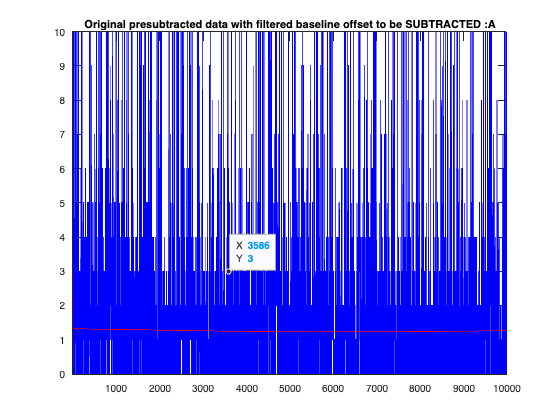

%Remove first null data point and initialize original timestream output and
%find spike-free rms, mean and median for possible offset correction in BAS code 
if (colA ~= 0)
    I_A=I_A(2:end);
    handlesA.base=I_A;
    rms1=std(I_A);
    qrms1=(I_A < 5*rms1);   % Data that isn't part of major spike activity
    handlesA.rms=std(I_A(qrms1));
    handlesA.median=median(I_A(qrms1));
    handlesA.mean=mean(I_A(qrms1));
else
    disp('No A Channel data specified')
    handlesA.base=0;
    datastatA=0;
    peaklocA=0;
end  
if (colB ~= 0)
    I_B=I_B(2:end);
    handlesB.base=I_B;
    rms1=std(I_B);
    qrms1=(I_B < 5*rms1);   % Data that isn't part of major spike activity
    handlesB.rms=std(I_B(qrms1));
    handlesB.median=median(I_B(qrms1));
    handlesB.mean=mean(I_B(qrms1));    
else
    disp('No B Channel data specified')
    handlesB.base=0;
    datastatB=0;
    peaklocB=0;
end


%Apply slow drift correction to baseline (paramsfile parameters 5&6)
if driftwinA && colA 
    [I_A,basedrift]=Basedrift_Data(I_A,driftwinA,'A');
    handlesA.basedriftA=basedrift;
end
if driftwinB && colB 
    [I_B,basedrift]=Basedrift_Data(I_B,driftwinB,'B');
    handlesB.basedriftB=basedrift;
end


%Apply baseline threshold filter (paramsfile parameters 7&8) to subtract
%offset
if basethreshA && colA
    [I_A,baseoffset]=Basethresh_Data(I_A,basethreshA,'A');
    handlesA.baseoffsetA=baseoffset;
end

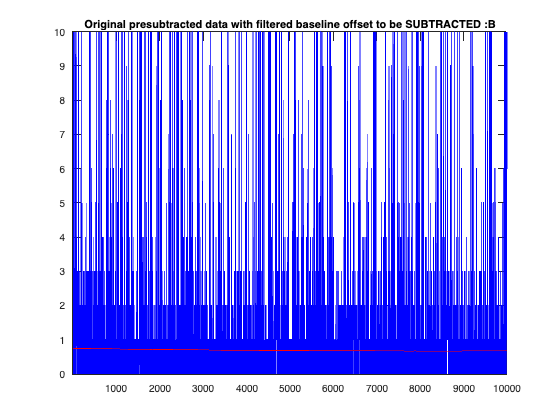

if basethreshB && colB 
    [I_B,baseoffset]=Basethresh_Data(I_B,basethreshB,'B');
    handlesB.baseoffsetB=baseoffset;
end

## Determine location and amplitudes of spikes in concatenated data set

***** Processing channel :A


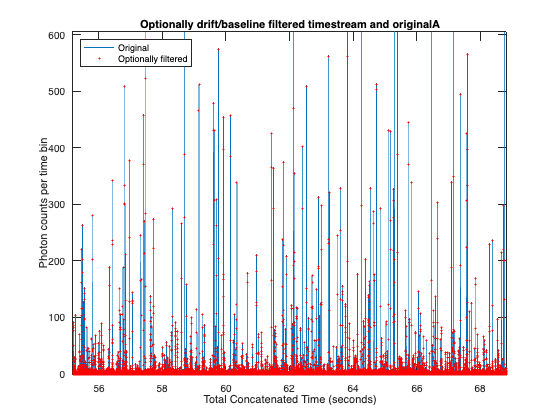

handles = struct with fields:
            base: [0 0 1 1 0 1 0 3 1 0 1 1 1 5 18 22 28 20 17 17 4 0 1 0 2 1 2 2 3 7 12 6 4 1 2 0 0 1 2 0 0 0 2 2 0 1 2 1 2 1 3 1 13 25 23 8 4 1 2 1 2 0 1 0 1 3 1 2 2 1 0 3 4 3 1 2 1 1 1 0 5 2 0 0 2 1 3 2 8 21 21 15 10 4 4 1 2 3 0 1 1 1 0 3 1 4 0 1 1 … ]
             rms: 11.0061
          median: 1
            mean: 3.6221
     baseoffsetA: [1.3236 1.3235 1.3235 1.3235 1.3234 1.3234 1.3234 1.3233 1.3233 1.3233 1.3232 1.3232 1.3231 1.3231 1.3231 1.3230 1.3230 1.3230 1.3229 1.3229 1.3229 1.3228 1.3228 1.3227 1.3227 1.3227 1.3226 1.3226 1.3226 1.3225 1.3225 1.3225 1.3224 … ]
               d: [2×243726 double]
    spthreshtype: "mean"


spikethresh = 7.2442

Chosen spike finding threshold setting is the 2*mean of 5-sigma filtered data set 


spikethresh = 10

**** OVERRIDE: Restricted to Upper Bound / 100 as lower limit ****
Setting lower spike acceptance threshold to:10
Retaining subthreshold spikes between5 and10 in Handles structure


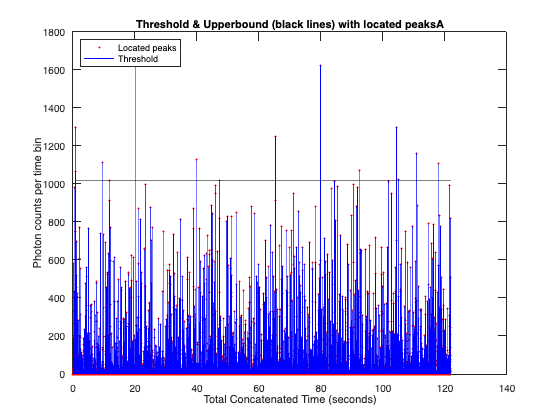

Checking interspike timing distribution and removing events closer than corrt
-----------------------------------------
Removing98 intertime violation events from3746 total events


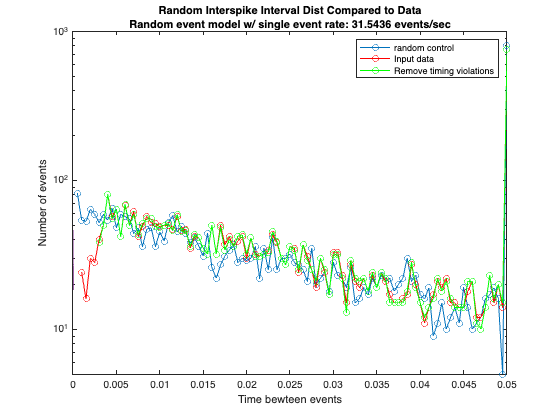

if (colA ~= 0)
     [datastatA,handlesA,peaklocA]=burst_data(I_A,tbin,corrt, dofit, 'A', handlesA);
end

***** Processing channel :B


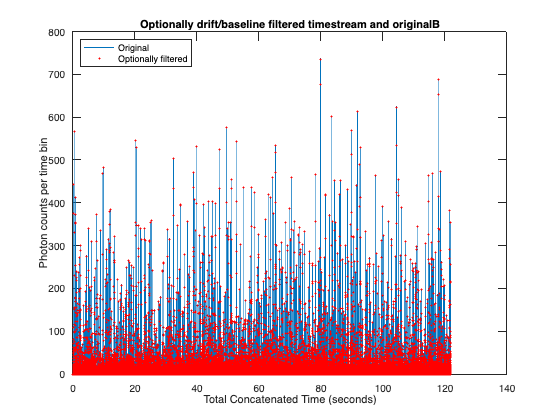

handles = struct with fields:
            base: [0 0 0 0 0 0 0 0 1 1 0 0 4 7 19 13 18 16 20 8 2 1 0 0 0 2 1 2 9 16 31 6 2 1 0 1 0 0 0 0 0 0 1 2 1 0 0 2 1 3 2 1 2 31 17 7 1 2 0 0 1 0 0 2 0 0 0 0 0 1 1 4 0 1 0 0 1 0 1 2 3 3 1 1 1 1 1 3 5 7 14 11 3 1 2 1 0 1 3 2 3 0 0 1 1 1 0 2 0 2 … ]
             rms: 6.6846
          median: 1
            mean: 2.2612
     baseoffsetB: [0.7497 0.7496 0.7496 0.7496 0.7496 0.7495 0.7495 0.7495 0.7495 0.7494 0.7494 0.7494 0.7493 0.7493 0.7493 0.7493 0.7492 0.7492 0.7492 0.7492 0.7491 0.7491 0.7491 0.7491 0.7490 0.7490 0.7490 0.7490 0.7489 0.7489 0.7489 0.7489 0.7488 … ]
               d: [2×243726 double]
    spthreshtype: "mean"


spikethresh = 4.5225

Chosen spike finding threshold setting is the 2*mean of 5-sigma filtered data set 


spikethresh = 5

**** OVERRIDE: Restricted to Upper Bound / 100 as lower limit ****


spikethresh = 10

**** OVERRIDE: Restricted to 10 cnts as lower limit - arbitrary Poisson noise limit ****
Setting lower spike acceptance threshold to:10
Retaining subthreshold spikes between5 and10 in Handles structure


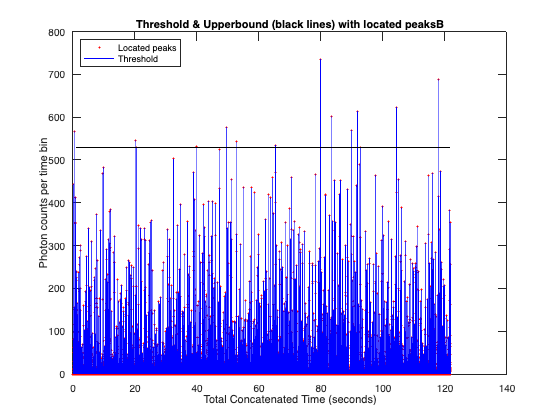

Checking interspike timing distribution and removing events closer than corrt
-----------------------------------------
Removing87 intertime violation events from3375 total events


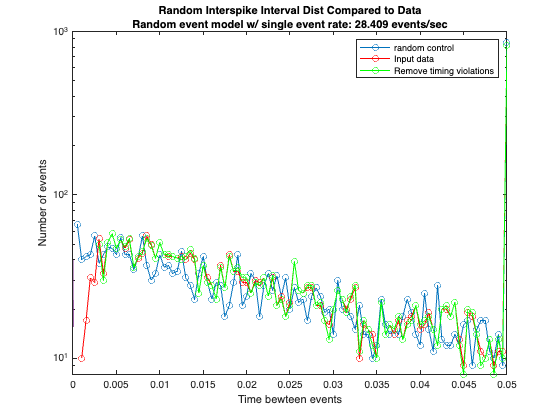

if (colB ~= 0)
    [datastatB,handlesB,peaklocB]=burst_data(I_B,tbin,corrt, dofit, 'B', handlesB);
end

## Check rate of strikes and single particle limit

Use a few stats to determine if single particle limit holds for this dataset

do_strikestats=true

do_strikestats = logical
   1



if do_strikestats
% Determine some statistics about detected spikes

if (colA ~= 0)
    numbins = length(handlesA.strike)
    disp('>>>>>>>Channel A')
    numspA = sum(handlesA.strike);
    disp(strcat('Number events above A threshold: ',num2str(numspA)));
% If random, prob of spikes in single bin and multiple adjacent bins
    p0bin1A= (numbins-numspA) / numbins;
    p1bin1A= numspA / numbins;
    disp(strcat('Prob of 0 event in a bin: ',num2str(p0bin1A)));
    disp(strcat('Prob of 1 event in a bin: ',num2str(p1bin1A)));
    disp(strcat('Prob of 2 events in a bin based on P(n=1)^2: ',num2str(p1bin1A^2)));
    
    disp(' ')
    disp(strcat('Fraction of events that are double strikes ',num2str((p1bin1A^2*numbins)/numspA) ));
    
    %average value and prob of a subthreshold event in subthresh band
    avgsubampA=mean(handlesA.subthreshstrikeamp);
    probsubampA= sum(handlesA.subthreshstrike)/numbins;
    disp('avg A channel contribution of subthresh events is') 
    overampsubA=probsubampA*avgsubampA
    

    
% Prob of subthreshold events contributing to more than 10%     
    
end


if (colB ~= 0)
    numbins = length(handlesB.strike)
    disp('>>>>>>>Channel B')
    numspB = sum(handlesB.strike);
    disp(strcat('Number events above B threshold: ',num2str(numspB)));
% If random, prob of spikes in single bin and multiple adjacent bins
    p0bin1B= (numbins-numspB) / numbins;
    p1bin1B= numspB / numbins;
    disp(strcat('Prob of 0 event in a bin: ',num2str(p0bin1B)));
    disp(strcat('Prob of 1 event in a bin: ',num2str(p1bin1B)));
    disp(strcat('Prob of 2 events in a bin based on P(n=1)^2: ',num2str(p1bin1B^2)));

    disp(' ')
    disp(strcat('Fraction of events that are double strikes ',num2str((p1bin1B^2*numbins)/numspB) ));

    %average value and prob of a subthreshold event in subthresh band
    avgsubampB=mean(handlesB.subthreshstrikeamp);
    probsubampB= sum(handlesB.subthreshstrike)/numbins;
    disp('avg B channel contribution of subthresh events is') 
    overampsubB=probsubampB*avgsubampB
    

end

end

numbins = 243726

>>>>>>>Channel A


Number events above A threshold:3844


Prob of 0 event in a bin:0.98423


Prob of 1 event in a bin:0.015772


Prob of 2 events in a bin based on P(n=1)^2:0.00024875


Fraction of events that are double strikes0.015772


avg A channel contribution of subthresh events is


overampsubA = 0.0015

numbins = 243726

>>>>>>>Channel B


Number events above B threshold:3462


Prob of 0 event in a bin:0.9858


Prob of 1 event in a bin:0.014204


Prob of 2 events in a bin based on P(n=1)^2:0.00020177


Fraction of events that are double strikes0.014204


avg B channel contribution of subthresh events is


overampsubB = 9.5819e-04

## Cross-correlation of data sets

Determine fraction of events common to both channels using raw signal 

do_xcorr=true

do_xcorr = logical
   1


Both channels active: finding fractional overlap of events ...


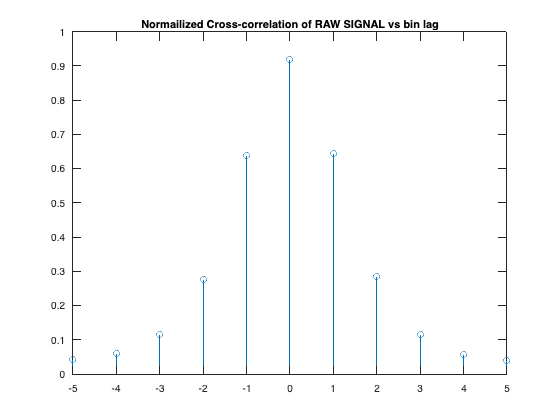

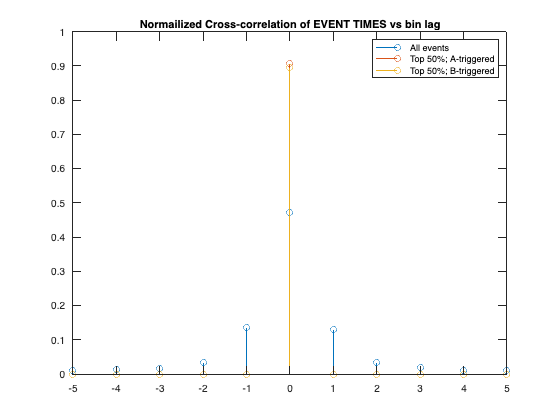

Event zero lag A-triggered, B-triggered, and auto-correlation AA, BB = 1  check


fracoverlapAB = 0.8205

fracoverlapBA = 0.8015

fracoverlapAA = 1

fracoverlapBB = 1

if (colA*colB*do_xcorr ~= 0)
    disp('Both channels active: finding fractional overlap of events ...')
    %Find typical upper bound using 10 largest strikes
    hold off;
    [c,lags]=xcorr(handlesA.base,handlesB.base,5,'normalized');
    stem(lags,c);
    title('Normailized Cross-correlation of RAW SIGNAL vs bin lag')
    figure
    hold off;
    [c,lags]=xcorr(handlesA.strike,handlesB.strike,5,'normalized');
    stem(lags,c);
    title('Normailized Cross-correlation of EVENT TIMES vs bin lag')

    
    sortA=sort(handlesA.strikeamp,'descend');  %sort descending
    sortB=sort(handlesB.strikeamp,'descend');
    UBA= median(sortA(1:10));
    UBB= median(sortB(1:10));
    AQ1=handlesA.strikeamp > 0.5*UBA;
    BQ1=handlesB.strikeamp > 0.5*UBB;


    hold on
    Atempstrike=handlesA.strike.*AQ1;
    Btempstrike=handlesB.strike.*AQ1;
    [c,lags]=xcorr(Atempstrike,Btempstrike,5,'normalized');
    stem(lags,c);
    Atempstrike=handlesA.strike.*BQ1;
    Btempstrike=handlesB.strike.*BQ1;
    [c,lags]=xcorr(Atempstrike,Btempstrike,5,'normalized');
    stem(lags,c);

    legend('All events','Top 50%; A-triggered','Top 50%; B-triggered')

    numberA=sum(handlesA.strike(AQ1));
    numberB=sum(handlesB.strike(BQ1));
    
    disp('Event zero lag A-triggered, B-triggered, and auto-correlation AA, BB = 1  check')
    fracoverlapAB= sum(handlesA.strike.*handlesB.strike.*AQ1)/numberA
    fracoverlapBA= sum(handlesB.strike.*handlesA.strike.*BQ1)/numberB

    fracoverlapAA= sum(handlesA.strike.*handlesA.strike.*AQ1)/numberA
    fracoverlapBB= sum(handlesB.strike.*handlesB.strike.*BQ1)/numberB
    handlesA.overlapAB=fracoverlapAB;
    handlesB.overlapAB=fracoverlapAB;
end

## Save results to .mat file and a pdf report


%Save processing and create PDF report
savebasresults=true

savebasresults = logical
   1


%Save processing and create PDF report
if savebasresults
  savepredone=Save_Preprocessed(PrePathName,PreFileName,datastatA,datastatB,handlesA,handlesB,peaklocA,peaklocB,readmePRE,versionnum)
end

tstr = datetime
   30Mar23-105436


version number:v1p4


newdir = "Preprocess_v1p4_30Mar23-105436"

savepredone = 1

# Part II

## FUNCTIONS

## Rolling window filter to remove baseline wander but retain overall mean of timestream 

function [cI,basedrift]=Basedrift_Data(I,driftwin,channel)

% Removes a smoothed baseline from timestream but retains overall mean of
% timestream; Use a 50 sample median filter (slow and memory intensive but largely insensitive to spikes) 
% followed by a 12000 sample averaging filter on that result (fast and
% roughly 6 second time constant with nominal 0.5 ms sampling

medianI=median(I);
qq=I-medianI;  %Removes median to roughly center baseline on zero
MF=medfilt2(qq,[1 fix(driftwin*50)]); % sets window size and filters
basedrift = MF+medianI;  %restores original amplitude
basedrift = smoothdata(basedrift,'gaussian',12000);

cI=I-basedrift;  %Remove drift but now there are negative values
cI=cI + medianI;  %non-drifting time stream possibly with some zeros
cI(cI<0)=0;       %zero any negative values


%Overplot data and baseline in zoomed in fashion
plot(I,'b');
hold on
plot(basedrift,'r');
xlim([1,10000]);
ylim([0,medianI*5]);  
title(strcat('Original data with drift overplotted :',channel));
hold off
%pause(3)


end


## DEPRECATED: Low-amp noise suppression (a.k.a. "cut threshold" or "basethresh")

In bd_175.m this is called "Cut threshold". This can be used to supress  (but not remove) a background signal before finding spikes and spike amps.  

% function [cI]=Basethresh_Data(I,basethresh,channel)
% % Used same median filter as used in Basedrift to fine a baseline which is then removed. Zeroes data 
% % below this base threshold curve in each channel but does
% 
% cI=I-basethresh;
% zpoints=find(cI < 0);
% if ~isempty(zpoints)
%     cI(zpoints)=-basethresh;
%     cI=cI+basethresh;    
% end
% 
% %Plot data w/ hash removed
% plot(cI,'.b');
% title(strcat('Data with base threshold applied to suppress low ampl. background',channel))
% pause(3)
% 
% 
% end

## Offset removal

In bd_175.m this is also called "Cut threshold". This routine can be used to subtract a background before finding spikes and spike amps. This subtracts a smoothed drifting function from the raw data and sets any values below zero to zero. The idea is to remove an unresolved, ubiquitous, luminous background that is adding to the event amplitudes. 

function [cI,baseoffset]=Basethresh_Data(I,basethresh,channel)
% Used same median filter as used in Basedrift to find a baseline but is then removed. Zeroes out any data 
% below zero value in each channel. 
% Use a 50 sample median filter (slow and memory intensive but largely insensitive to spikes) 
% followed by a 12000 sample averaging filter on that result (fast and
% roughly 6 second time constant with nominal 0.5 ms sampling


medianI=median(I);
qq=I-medianI;  %Removes median to roughly center baseline on zero
MF=medfilt2(qq,[1 fix(basethresh*50)]); % sets window size and filters
baseoffset = MF+medianI;  %restores original amplitude
baseoffset = smoothdata(baseoffset,'gaussian',12000);

cI=I-baseoffset;  %Remove drift but now there are negative values

cI(cI<0)=0;       %zero any negative values


%Overplot data and baseline in zoomed in fashion
plot(I,'b');
hold on
plot(baseoffset,'r');
xlim([1,10000]);
ylim([0,max([medianI*5,10]) ]);  %Handles cases with zero median value
title(strcat('Original presubtracted data with filtered baseline offset to be SUBTRACTED :',channel));
hold off
%pause(3)

end

## Save preprocessed results to .mat and PDF report

function savepredone=Save_Preprocessed(PrePathName,PreFileName,datastatA,datastatB,handlesA,handlesB,peaklocA,peaklocB,readmePRE,versionnum)
% save data and results

%Get information about this data run and create a director for this data store
[filebase, tstr]=Information(versionnum);
timestr=string(tstr);
newdir=strcat(filebase,'_',timestr)
mkdir(newdir)

%prefilenamereport=strcat(PrePathName,filebase,PreFileName,timestr,'Report.pdf');
prefilenamesave=strcat(PrePathName,newdir,'/',filebase,PreFileName,timestr,'.mat');

%Save all Matlab variables and states
save(prefilenamesave)
savepredone=1;
end


## Find burst location times and amplitudes (preprocess)

function [datastat,handles,peakloc]=burst_data(d,tbin, corrt, dofit, channel, handles)
%This is original 2013 preprocessing code used in MegaMan_V1.m and bd_175
%Some of the commented code is left to show comparison to what was - if
%commented it was not doing anything even in old code
%Channel data are mapped to appropriate old variables like handles
%Input variable channel is string to label channel being processed
%handles.medwin=5;    Not used in bd_175 either

handles.d=zeros(2,length(d));
handles.d(1,:)=[0:length(d)-1]*tbin;  %make time vector in seconds
handles.d(2,:)=d;   %Time data filtered by drift and basethresh is read in
%handles.base=d;     %Original time data unfiltered is read in


disp(strcat('***** Processing channel : ',channel))

%Show original data
figure
plot(handles.d(1,:),handles.base);  %show original time steam data
hold on;
plot(handles.d(1,:),handles.d(2,:),'.r');
title(strcat('Optionally drift/baseline filtered timestream and original ',channel))
legend('Original','Optionally filtered','Location','northwest')
xlabel('Total Concatenated Time (seconds)')
ylabel('Photon counts per time bin')
hold off


%%%%%%%%%
% Consider using a threshold level to define when burst boundary happens
% rather than always using zero
%
% Set an amplitude threshold for base of spike to 0, mean, median, rms, or 
% dynamic range (1/100) of large spike
%

%%%% Determine upper range of spike activity ; 30 is a heuristic parameter
    sortbase=sort(handles.base);
    UB= median(sortbase(end-30:end));
    
%%%% Determine lower bound (threshold) of trustable spike activity
%% Default to mean for most cases
handles.spthreshtype = "mean"
dynrange = 100; 
switch handles.spthreshtype
    case 'zero'
        spikethresh = 0
        disp('Chosen spike finding threshold setting is zero' )       
    case 'mean'
        spikethresh = 2*handles.mean
        disp('Chosen spike finding threshold setting is the 2*mean of 5-sigma filtered data set ' )       
    case 'median'
        spikethresh = 2*handles.median
        disp('Chosen spike finding threshold setting is the 2*median of 5-sigma filtered data set ' )       
    case 'rms'
        spikethresh = 2*handles.rms
        disp('Chosen spike finding threshold setting is the 2*rms of 5-sigma filtered data set ' )       
    case 'dynamicrange'
  % Estimate upper bound on events in a channel 
        spikethresh = round(UB/dynrange);  
        disp(strcat('Applying a 1/100 dynamic range threshold : ', num2str(spikethresh)))
        disp('Chosen spike finding threshold setting is UB/100 of data set ' )       
end

%%% Bound lower threshold has some constraints

if spikethresh < round(UB/dynrange)  % the dynamic range is minimum possible
    spikethresh = round(UB/dynrange)
    disp('**** OVERRIDE: Restricted to Upper Bound / 100 as lower limit ****' )
end
if spikethresh < 10   % set 10 as a lower limit in all cases due to shot noise
    spikethresh = 10
    disp('**** OVERRIDE: Restricted to 10 cnts as lower limit - arbitrary Poisson noise limit ****' )

end

%%%% Store parameters in structure for later use    
    handles.spthresh = spikethresh;
    handles.UB = UB;

%%%%%%%%%

strike=d;  %data imported to function (not baseline)

% Set a lower bound for spike finding below the threshold as a way of estimating subthreshold
% activity later
disp(strcat('Setting lower spike acceptance threshold to: ',num2str(spikethresh)));
disp(strcat('Retaining subthreshold spikes between ',num2str(spikethresh/2),' and ',num2str(spikethresh),' in Handles structure'));
strike(strike < spikethresh/2)=0;   % Set lower amplitude to find the edge of spikes

%Guarentee zeroed end points
strike(1)=0; strike(2)=0; strike(end)=0; strike(end-1)=0;
again1=1; again2=1;
while(again2 == 1)
    t=find(strike==max(strike));
    t=max(t);  %This could be 2nd pnt, 2nd to last pnt or in middle of data 
    i=1; rightend=1; leftend=1; again1=1;
%    if (t==19997)
 %       t
 %   end;
    strike(t) = -1; %tip of peak in single event set to -1
    while (again1 >= 1)     
        ti_index=max(max([mod(t+i,size(strike,2)),1])); %Because nonzero index needed
        if (abs(strike(ti_index))>0 && rightend)    %  See comment above about threshold
            strike(ti_index)=0;
        else
            rightend=0;
        end
        ti_index=max([mod(t-i,size(strike,2)),1]);
        if (abs(strike(ti_index))>0 && leftend)    %  See comment above about threshold
            strike(ti_index)=0;
        else
            leftend=0;
        end

        i=i+1;
        again1=rightend+leftend;
    end % again1

    
    if (max(strike)<=0)  
        again2=0; 
    end
end  % again2

handles.strike=-strike;
%handles.strikeamp=-strike.*handles.base;   changed 24 June 2020
handles.strikeamp=-strike.*handles.d(2,:);

%axes(handles.Event_data);
figure
plot(handles.d(1,:),handles.strikeamp,'r.');
%axis(handles.lim);
hold on;
%plot(handles.d(1,:),handles.base,'b');
plot(handles.d(1,:),handles.d(2,:),'b');
plot([1,handles.d(1,end)], [UB,UB],'k-')
title(strcat('Threshold & Upperbound (black lines) with located peaks ',channel))
legend('Located peaks','Threshold','Location','northwest')
xlabel('Total Concatenated Time (seconds)')
ylabel('Photon counts per time bin')
hold off;

% Store some of the spike data below the threshold for later noise and
% single event prob analysis; zero these data in main propagated data
% variables
handles.subthreshstrike=handles.strike.*(handles.strikeamp < spikethresh);
handles.subthreshstrikeamp=handles.strikeamp.*(handles.strikeamp < spikethresh);
handles.strike=handles.strike.*(handles.strikeamp > spikethresh);
handles.strikeamp = handles.strikeamp.*(handles.strikeamp > spikethresh);

%Consider peaks away from very edge of data set; 15 bin buffer is 
%sized for later Gaussian model fit to events
peakloc=find(handles.strikeamp > 0);   %All burst events found   
peakloc=peakloc(find(peakloc > 15));
peakloc=peakloc(find(peakloc < size(handles.strikeamp,2)-15));
npeaks=size(peakloc,2);
params=struct('mean',[1:npeaks],'sig',[1:npeaks],'A',[1:npeaks]);


% Check interspike timing statistics and remove events too closely spaced
disp('Checking interspike timing distribution and removing events closer than corrt')
ISI_check(handles,tbin,corrt)


%Do fit of Gaussian model to each event if dofit flag set in parameter
while (dofit)  %%%%%%%Hook to turn off Gaussian fitting - remove datastat=1 too %%%%%%
for i=1:npeaks   *handles.d(2,:)
%    fitme=handles.base(peakloc(i)-10:peakloc(i)+10); %start with general spike zone
    fitme=handles.d(2,peakloc(i)-10:peakloc(i)+10); %start with general spike zone
    dzone=fix(2*sum(fitme)/max(fitme)); % refine zone assuming Gaussian peak
%    fitme=handles.base(peakloc(i)-dzone:peakloc(i)+dzone);
    fitme=handles.d(2,peakloc(i)-dzone:peakloc(i)+dzone);
    x=[peakloc(i)-dzone:peakloc(i)+dzone];
    [A, mu, sigma] = fitgauss(fitme, x, max(fitme), peakloc(i), 3);
    params.mean(i)=mu;
    params.sig(i)=sigma;
    params.A(i)=A/sqrt(2*3.1415*sigma^2); %A is now amplitude
%    hold off; plot(x,fitme,'+');
%    hold on; plot(x,params.A(i)*exp(-(x-mu).^2/2/(params.sig(i)^2)),'r');
%    pause(1);
end %gauss fit
q=find((params.sig<10) & (params.sig>0)&(params.A<2*max(handles.strikeamp))&(params.A>0));    
datastat=struct('mean',params.mean(q),'sig',params.sig(q),'A',params.A(q));
dofit=0;
end %while
datastat=1;

%Reassign large, unused variables
qq=1; d=1; strike=1; zpoints=1; IX=1; MF=1; baseline=1;


end

## Check intervals between events (ISI)

function ISI_check(handles,tbin,corrt)
% Uses events locations in peakloc and timestream stored in handles structure
% to generate interspike interval plots compared to simple single-rate
% poisson model. The sampling time tbin and the correlation time (~width of a
% burst) corrt are used to exclude events that are too close in time.

nsamples=length(handles.strikeamp(:));  %number of sample bins in concatenated data
nhistbins=100; %consider sampletime*nhistbins seconds of event spacing (typically 100ms)
%Check interspike interval using generated time stream and a single
%population model prediction based on random times and same avg rate
striketimesm=randi([1,nsamples],sum(handles.strike),1);  
rtm=sort(striketimesm); %chronological order of event bins
peakshm=circshift(rtm,[1,0]);
peakdiffm=rtm - peakshm;  % This spacing (ISI) gives statistical measure of

%For reference, model of single population distribution with same avg event rate
% If multiple species, events should still be uncorrelated like 1 species
% of higher rate
xoutm=[1:nhistbins];
nm=hist(peakdiffm(2:end-1),xoutm);   %hist of random samples for control
figure
semilogy(xoutm*tbin,nm,'-o')
subtitle=strcat("Random event model w/ single event rate: ",...
    num2str(length(rtm)/(tbin*nsamples))," events/sec");
title({'Random Interspike Interval Dist Compared to Data';subtitle})
xlabel('Time bewteen events')
ylabel('Number of events')
hold on
%Do again with real data shifted for comparison; should yield same powerlaw
%slope; Overplot distributions
qq=(handles.strikeamp(:) > 0);
striketimesd=[1:nsamples]';  %need transpose to switch index order
striketimesd=striketimesd(qq); %indices where strikes occurred
rtd=sort(striketimesd);
peakshd=circshift(rtd,[1,0]);
peakdiffd=rtd - peakshd;
xoutd=[1:nhistbins];
nd=hist(peakdiffd(2:end-1),xoutd);   %hist of random samples for control
semilogy(xoutd*tbin,nd,'-ro')
legend('Noiseless Model','Simulated Data','Location','northeast')


%Find real data interspike intervals that don't violate correlation time
%parameter corrt; keep first event of two that are too close; arbitrary
%Would be better to keep larger amplitude event
dontkeep=(abs(peakdiffd) < round(corrt/tbin)); %logical indexing
rr=striketimesd(dontkeep);
handles.strikeamp(rr)=0;    %zero timing violation amplitude
handles.strike(rr)=0;       % zero the strike flag as well


% Now show with sub correlation time events removed
disp('-----------------------------------------');
ntotevents=sum(handles.strike);
displine=strcat('Removing ',num2str(length(rr)),' intertime violation events from ', ...
num2str(ntotevents),' total events');
disp(displine);
qq=(handles.strikeamp(:) > 0);
striketimesd=[1:nsamples]';  %need transpose to switch index order
striketimesd=striketimesd(qq); %indices where strikes occurred
rtd=sort(striketimesd);
peakshd=circshift(rtd,[1,0]);
peakdiffd=rtd - peakshd;
xoutd=[1:nhistbins];
nd=hist(peakdiffd(2:end-1),xoutd);   %hist of random samples for control
semilogy(xoutd*tbin,nd,'-go')



%Fit exponential model to distribution
mymodel = fittype('a*exp(b*n*x)','problem','n');
opts = fitoptions(mymodel);
set(opts,'normalize','on')
xdata=xoutd*tbin; ydata=nd;
[fit4,gof4,out4] = fit(xdata(1:end-1)',ydata(1:end-1)',mymodel,opts,'problem',{-1});
hold on; 
semilogy(xdata*tbin,fit4(xdata)); 
hold off;
legend('random control','Input data','Remove timing violations', 'Location','northeast')

hold off
% 'Predicted fraction less than ISI threshold',nm(end)/sum(nm)
% 'Data fraction less than ISI threshold',n(end)/sum(n)


end

## Outputs code version information 

function [prepfile, tstr]=Information(versionnum)
% Display version and hold introductory information


prepfile=strcat('Preprocess_',versionnum);

tstr=datetime('now');
tstr.Format = 'ddMMMyy-HHmmss'

disp(strcat('version number: ',versionnum))
%disp(strcat('Output file name: ',strcat(prepfile,'-Report',string(tstr),'.pdf')))

end
